BPSK

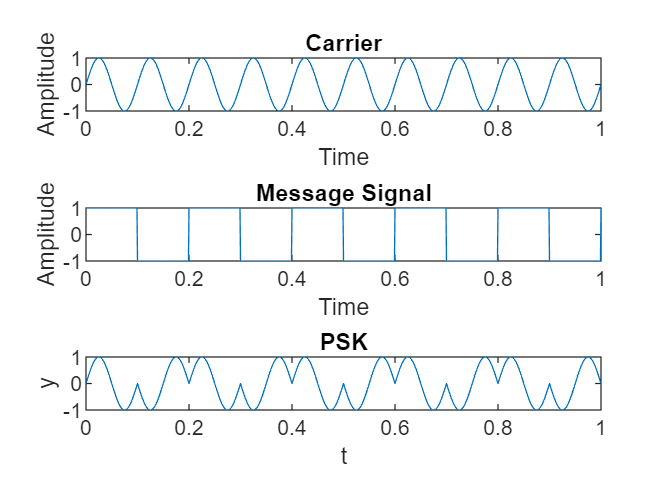

clc 
close all 
clear all 
t=0:.001:1; 
fc=input('Enter frequency of Carrier Sine wave: ');
fm=input('Enter Message frequency : ');
amp=input('Enter Carrier & Message Amplitude(Assuming Both Equal):');
c=amp.*sin(2*pi*fc*t);% Generating Carrier Sine
subplot(3,1,1) %For Plotting The Carrier wave
plot(t,c)
xlabel('Time')
ylabel('Amplitude')
title('Carrier')
m=square(2*pi*fm*t);% For Plotting Message signal
subplot(3,1,2)
plot(t,m)
xlabel('Time')
ylabel('Amplitude')
title('Message Signal')% Sine wave multiplied with square wave in order to generate PSK
x=c.*m;
subplot(3,1,3) % For Plotting PSK (Phase Shift Keyed) signal
plot(t,x)
xlabel('t')
ylabel('y')
title('PSK')

QPSK

clc
clear all
close all

%%
data=input('Enter the data for qpsk: - ');

last = length(data);
t=1;
disp(last)

     4



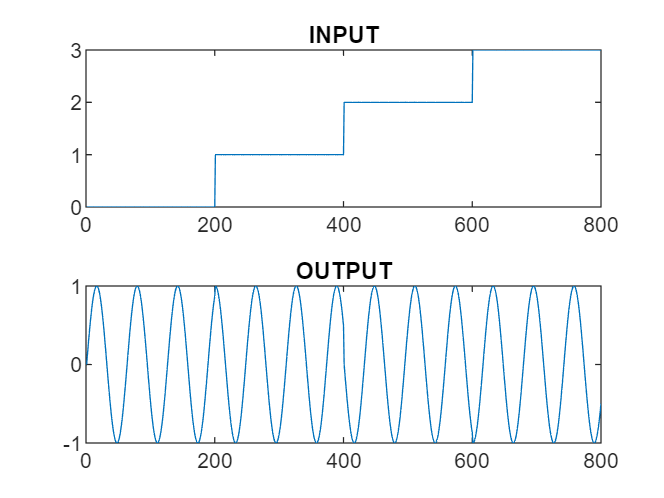

for start = 1:last
    
    if (data(start)==00)     %% 00
        for j=0:0.1:19.9
            q(t)=0;
            o(t)=sin(j);    %% 0 degree
            t=t+1;
        end
        
    elseif (data(start)==01) %% 01
        for j=0:0.1:19.9
            q(t)=1;
            o(t)=cos(j);    %% 90 degree
            t=t+1;
        end
        
    elseif (data(start)==10) %% 10
        for j=0:0.1:19.9
            q(t)=2;
            o(t)=-sin(j);   %% 180 degree
            t=t+1;
        end
        
    else %(data(start)==11) %% 11
        for j=0:0.1:19.9
            q(t)=3;
            o(t)=-cos(j);   %% 270 degree
            t=t+1;
        end    
    end
end

subplot(2,1,1)
plot(q);
title('INPUT');

subplot(2,1,2)
plot(o);
title('OUTPUT');

ASK

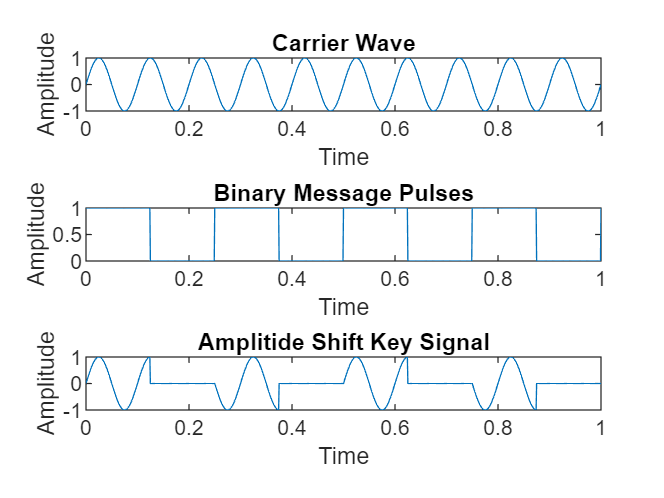

clc 
clear all 
close all

fc=input('Enter the freq of Sine Wave carrier:');
fp=input('Enter the freq of Periodic Binary pulse (Message):');
amp=input('Enter the amplitude (For Carrier & Binary Pulse Message):');
t=0:0.001:1; % For setting the sampling interval
c=amp.*sin(2*pi*fc*t);% For Generating Carrier Sine wave
subplot(3,1,1) %For Plotting The Carrier wave
plot(t,c)
xlabel('Time')
ylabel('Amplitude')
title('Carrier Wave')
m=amp/2.*square(2*pi*fp*t)+(amp/2);%For Generating Square wave message
subplot(3,1,2) %For Plotting The Square Binary Pulse (Message)
plot(t,m)
xlabel('Time')
ylabel('Amplitude')
title('Binary Message Pulses')
w=c.*m; % The Shift Keyed Wave
subplot(3,1,3) %For Plotting The Amplitude Shift Keyed Wave
plot(t,w)
xlabel('Time')
ylabel('Amplitude')
title('Amplitide Shift Key Signal')